# Pattern Tapering Lab

There are many techniques that can be applied to generate antenna patterns that have some desirable characteristics. In this lab, we look at how we can reduce the sidelobes in the antenna pattern while sacrificing some main beam width.

Before running this lab, ensure that you have already collected the calibration weights using the "Calibrate Antenna" livescript.

## Setup

First, put the HB100 transmitter as close to boresight as possible. For this lab to work, the transmitter has to start at boresight.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

We also load the frequency of the transmitter being used.

load('HB100_Fc.mat','fc_hb100');

Key variables for this lab:

sidelobeLevel = -30;   % maximum sidelobe level (in dB relative to the mainlobe peak)
normalizeResults = false;                 % normalize the tapered array pattern

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

## Collect Antenna Pattern

In this lab, we use the AntennaInteractor to collect the antenna pattern for us. For more detail on how to collect the antenna pattern, visit the "Antenna Pattern Lab".

### Pattern Without Tapering

First, collect the antenna pattern without setting any tapering. We do this using a function provided by the AntennaInteractor. To see how this is done in more detail, see the "Antenna Pattern Lab". Before collectnig the pattern, we ensure that the weights are set to the default calibration weights, meaning that no taper is applied.

steerangles = -90:0.5:90;
ai.updateAnalogWeights(calibrationweights.AnalogWeights);
patternData = ai.capturePattern(steerangles);
patWithoutTaper = mag2db(helperGetAmplitude(patternData));

### Pattern With Tapering

Next, we apply a taper to the individual elements of the array using Taylor windowing in order to reduce the pattern sidelobe level.

First we generate the Taylor window for the desired number of sidelobes at the desired sidelobe level.

nElements = 8;
nConstSidelobes = 2;  % number of nearly constant-level sidelobes adjacent to the mainlobe
taper = taylorwin(nElements,nConstSidelobes,sidelobeLevel);

Next we normalize the taper amplitude and reshape it so into the correct shape for the subarrays on the Phaser.

taper = taper / max(taper);
taper = [taper(1:4) taper(5:8)];

Finally, we adjust the taper using the calibration weights and set the new weights on the AntennaInteractor. These new weights will be used to generate the beam pattern instead of the default calibration weights. We normalize the tapering for each subarray before updating the weights.

taper = analogWeightsCalAdjustment(taper,calibrationweights.AnalogWeights);
if normalizeResults == 1
    taper = taper ./ max(abs(taper));
end
ai.updateAnalogWeights(taper);

With the analog weights updated, we once again collect the antenna pattern.

patternData = ai.capturePattern(steerangles);
patWithTaper = mag2db(helperGetAmplitude(patternData));

### Pattern Comparison

Now that we have collected the antenna pattern with and without tapering applied, we can see the effect of the tapering.

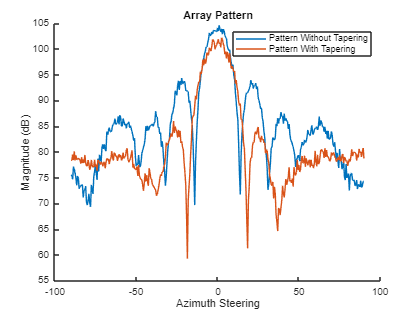

% Plot the antenna pattern
ax = axes(figure);
hold(ax,"on");
plot(ax,steerangles,patWithoutTaper-max(normalizeResults*patWithoutTaper),DisplayName="Pattern Without Tapering");
plot(ax,steerangles,patWithTaper-max(normalizeResults*patWithTaper),DisplayName="Pattern With Tapering");
if normalizeResults == 1;
    title(ax,'Normalized Array Pattern');
else
    title(ax,'Array Pattern');
end
xlabel(ax,'Azimuth Steering');
ylabel(ax,'Magnitude (dB)');
legend(ax);

% Perform cleanup
cleanup(ai);